# Project 10 (Rocket height)

6.7 and 6.14 in book

%{
t
   originally from 
Author: Tori Testa
Version: 1.0
Date: 2026-04-04
Purpose:
   -
Input:
   -
Output:
   -
Engineering Algorithems:
   -
MATLAB tools/functions:
   -
Reflection
   -
%}

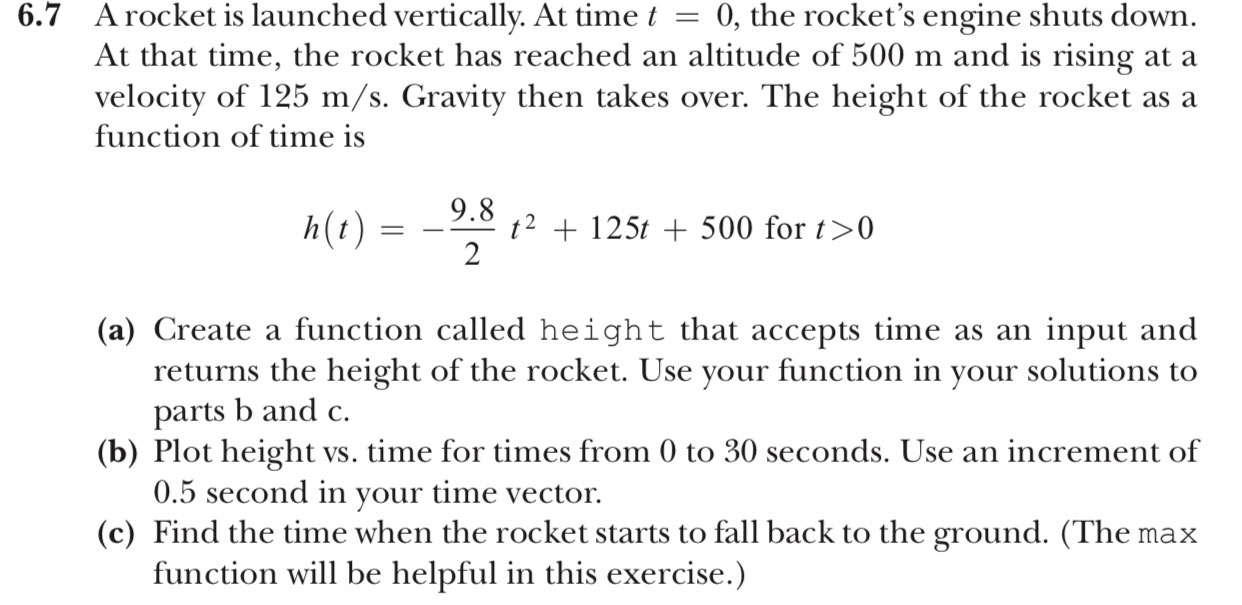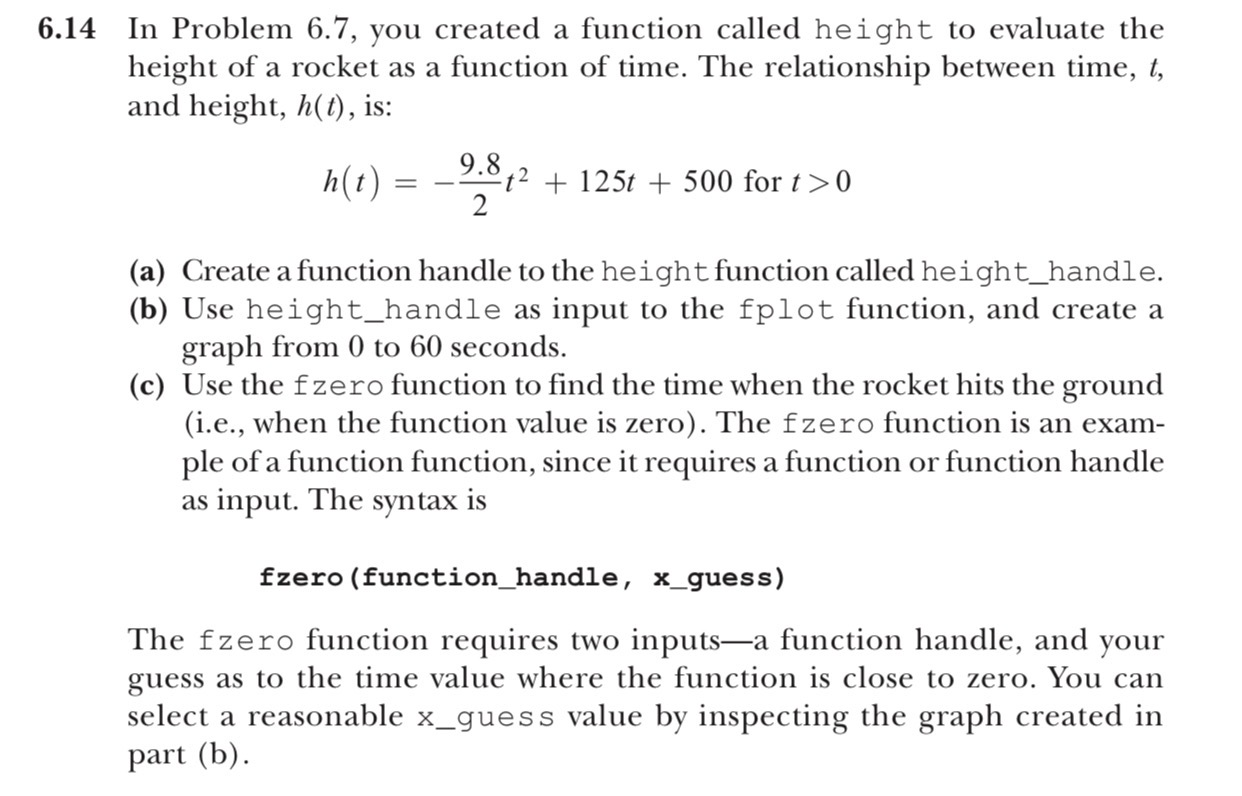

clc
clear

function h = height(t) % creates the height function
h = (-9.8/2)*(t.^2) + (125*t) + 500; % defines h from the problem
end

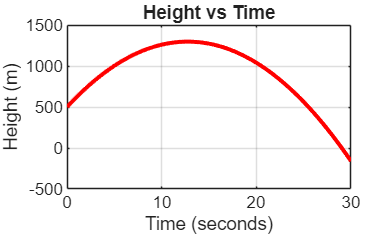

% plot of the rocket's height vs time
t = 0:0.5:30;  % defines t on the interval 0 to 30s
h = height(t); % calls the height function
% plot of time vs height
plot(t, h, 'r-', 'linewidth', 2) % the line is red with a width of 2
title('Height vs Time') % titles the plot
xlabel('Time (seconds)') % labels the x axis
ylabel('Height (m)') % labels the y axis
grid on % turns teh grid lines on

% find time rocket starts to fall back to ground (the max)
syms t % defines t as a symbollic variable
H = (-9.8/2)*(t.^2) + (125*t) + 500; % defines the height equation
v = diff(H,t); % defines velocity as the derivative of height
fall = solve(v == 0, t); % solves for when v is 0
peak = double(fall); % makes the value of fall numeric
fprintf('The rocket starts to fall to the ground at %g seconds.', peak) % displays the time the rocket begins to fall

The rocket starts to fall to the ground at 12.7551 seconds.

% creates function to handle the height function
height_handle = @(t) (-9.8/2)*(t.^2) + (125*t) + 500;

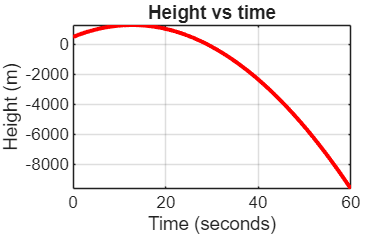

% plots the height handle function
fplot(height_handle, [0 60], 'r-', 'LineWidth', 2) % the line is red, with a width of 2
xlabel('Time (seconds)') % labels the x axis
ylabel('Height (m)') % labels the y axis
title('Height vs time') % titles the plot
grid on % turns the grid lines on

% Display the maximum height of the rocket
peakHeight = height(peak); % finds the height at the maximum point
fprintf('The peak height of the rocket is %g meters.\n', peakHeight); % displays the max height

The peak height of the rocket is 1297.19 meters.


hit = fzero(height_handle, 30); % finds where the rocket hits the ground (h=0)
fprintf('The rocket hits the ground at %g seconds', hit) % displays when the rocket hits the ground

The rocket hits the ground at 29.0257 seconds